clear ;clc;close all
%Sistem stanja
%parametri sistema
g= 9.81;%
m= 0.03;%
R= 0.04;%
J_w= m*R^2/2;%
M=0.6;%
W=0.14;
H=0.144;
L=H/2;
J_psi=M*L^2/3;
J_m=1e-5;
R_m=6.69;
K_b=0.468;
K_t=0.317;
n=1;
f_m=0.0022;
f_w=0.0001

f_w = 1.0000e-04

%prarametri e
e11=(2*m+M)*R^2+2*J_w+2*n^2*J_m;
e12=M*L*R-2*n^2*J_m;
e22=M*L*L+J_psi+2*n^2*J_m;
detE=e11*e22-e12^2;
% alfa beta sigma
alfa=n*K_t/R_m;
beta=n*K_t*K_b/R_m+f_m

beta = 0.0244

sig=beta+f_w;
%koeficijenti matrice A
a32=-g*M*L*e12/detE;
a42= g*M*L*e11/detE;
a33=-2*(sig*e22+ beta*e12)/detE;
a43= 2*(sig*e12 + beta*e11)/detE;
a34= 2*beta*(e22+e12)/detE;
a44= -2*beta*(e11+e12)/detE;
%matrica A
A=[0 0 1 0;0 0 0 1;...
    0 a32 a33 a34;0 a42 a43 a44]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0 -409.7184 -162.5990  162.1273
         0  269.6273   78.3429  -78.1496


%koeficijenti matrice B
b3=alfa*(e22+e12)/detE;
b4=-alfa*(e11+e12)/detE;
%matrica B
B=[0 0;0 0;b3 b3;b4 b4]

B =          0         0
         0         0
  157.5798  157.5798
  -75.9576  -75.9576


%matrice C i D
C=[1 0 0 0;0 1 0 0;...
    0 0 1 0;0 0 0 1]

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D=zeros(4,2)

D =      0     0
     0     0
     0     0
     0     0



G=minreal(ss(A,B,C,D))

G =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -409.7  -162.6   162.1
   x4       0   269.6   78.34  -78.15
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3   157.6   157.6
   x4  -75.96  -75.96
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
   y4   0   0
 
Continuous-time state-space model.



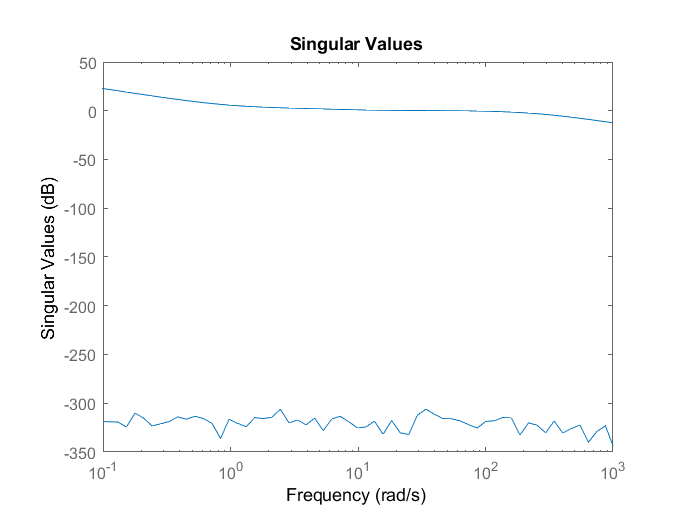

sigma(G)

%funkcije prenosa
G=tf(minreal(ss(A,B,C,D)))

G =
 
  From input 1 to output...
          157.6 s^2 + 8.398e-13 s - 1.137e04
   1:  ----------------------------------------
       s^4 + 240.7 s^3 - 264.1 s^2 - 1.174e04 s
 
                 -75.96 s - 5.364
   2:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
        157.6 s^2 + 1.12e-12 s - 1.137e04
   3:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
               -75.96 s^2 - 5.364 s
   4:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
  From input 2 to output...
          157.6 s^2 + 8.398e-13 s - 1.137e04
   1:  ----------------------------------------
       s^4 + 240.7 s^3 - 264.1 s^2 - 1.174e04 s
 
                 -75.96 s - 5.364
   2:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
        157.6 s^2 + 1.12e-12 s - 1.137e04
   3:  ------------------------------------
       s^3 + 240.7 s^2 - 264.1 s - 1.174e04
 
              

pole(G)

ans =          0
 -241.6405
    7.4312
   -6.5393
 -241.6405
    7.4312
   -6.5393
 -241.6405
    7.4312
   -6.5393


tzero(G)


ans =

  0×1 empty double column vector



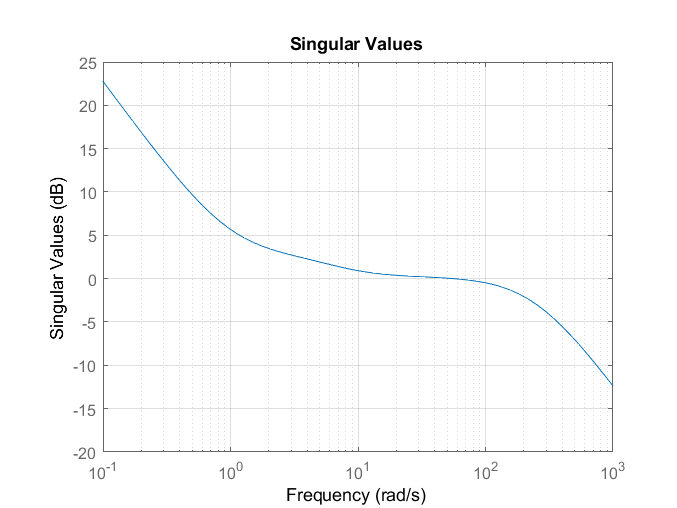

figure()
sigma(G)
ylim([-20 25])
grid on
xlim([0.1 1000])

%te